## Исследование управляемости

function doC(A, B)
    % МАТРИЦА УПРАВЛЯЕМОСТИ %%%%%%%%%%%%%%%%%
    disp('Матрица управляемости');
    Co = ctrb(A, B)
    rank_Co = rank(Co);
    fprintf('Ранг матрицы управляемости: %d\n', rank_Co);
    if rank_Co == size(A, 1)
        fprintf('Система полностью управляемая.\n');
    else
        fprintf('Система не полностью управляемая.\n');
    end
    
    % СОБСТВЕННЫЕ ЧИСЛА И ХАУТУС %%%%%%%%%%%
    eigenvalues = eig(A);
    fprintf('\n\nСобственные числа системы:\n');
    disp(eigenvalues);
    for i = 1:length(eigenvalues)
        fprintf("Матрица Хаутуса для собственного числа %d + %dj\n", real(eigenvalues(i)), imag(eigenvalues(i)));
        Hautus = [A - eigenvalues(i) * eye(size(A)), B]
        rank_Hautus = rank(Hautus);
        fprintf('Ранг матрицы Хаутуса: %d\n', rank_Hautus);
        if rank_Hautus == size(A, 1)
            fprintf('Собственное число управляемо.\n\n');
        else
            fprintf('Собственное число не управляемо.\n\n');
        end
    end
    
    % ЖОРДАН %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [P, J] = jordan(A);

    fprintf('\nКомплексная жорданова форма матрицы A:\n');
    disp(J);

    [P1, J1] = cdf2rdf(P, J);

    disp('Вещественная жорданова форма матрицы A:');
    disp(J1);

    disp('Вещественная P:');
    disp(P1);

    disp('Вещественная P^{-1}:');
    disp(inv(P1));

    disp('Новая матрица B:');
    disp(P1\B);    
end

function [W_inv] = gramAt(A, B, t)    
    % Определяем функцию для подынтегрального выражения
    gramian_integrand = @(tau) expm(A*tau) * B * B' * expm(A'*tau);
    
    % Вычисляем интеграл численно
    W_c_t = integral(@(tau) gramian_integrand(tau), 0, t, 'ArrayValued', true);
    
    disp('Грамиан управления в точке t = 3:');
    disp(W_c_t);

    if (rank(W_c_t) == size(W_c_t, 1))
        disp('Грамиан управления в точке t = 3 обратный:');
        W_inv = inv(W_c_t);
    else
        disp('Грамиан управления в точке t = 3 всевдо-обратный:');
        W_inv = pinv(W_c_t);
    end
    disp(W_inv);

    ev = eig(W_c_t);
    disp('Его собственные числа:');
    disp(ev);
    
end

function plot_control_and_state(A, B, x1, t1, Gramian_inv, path)
    % Функция для расчета управления и состояния системы и их отображения
    % A, B - матрицы системы x' = Ax + Bu
    % x1 - конечное состояние x(t1)
    % t1 - время достижения состояния x1

    % Шаг времени для моделирования
    dt = 0.01;
    t_vals = 0:dt:t1;

    % Расчет управления
    u_vals = zeros(1, length(t_vals));
    x_vals = zeros(size(A, 1), length(t_vals));

    for k = 1:length(t_vals)
        t = t_vals(k);
        % Управление u(t)
        exp_term = expm(A' * (t1 - t));
        u_vals(k) = B' * exp_term * Gramian_inv * x1;

        % Состояние x(t)
        x_vals(:, k) = expm(A * t) * zeros(size(A, 1), 1) + ...
                       integral(@(tau) expm(A * (t - tau)) * B * ...
                       (B' * expm(A' * (t1 - tau)) * Gramian_inv * x1), 0, t, 'ArrayValued', true);
    end

    % Графики
    figure;
    subplot(2, 1, 1);
    plot(t_vals, u_vals, 'LineWidth', 2);
    grid on;
    xlabel('Время, t');
    ylabel('u(t)');
    title('Управление u(t)');

    subplot(2, 1, 2);
    plot(t_vals, x_vals, 'LineWidth', 2);
    grid on;
    xlabel('Время, t');
    ylabel('Состояния x');
    legend('x1', 'x2', 'x3');
    title('Состояние системы x(t)');

    exportgraphics(gcf, path, 'Resolution', 300);
end


% Данные задачи 1
A = [-1 1 0; -2 -4 -1; 2 2 -1];
B = [2; 3; -1];
x1 = [1; -3; 3];
t1 = 3;

doC(A, B);

Матрица управляемости


Co =      2     1   -16
     3   -15    47
    -1    11   -39


Ранг матрицы управляемости: 3
Система полностью управляемая.


Собственные числа системы:
  -2.0000 + 1.0000i
  -2.0000 - 1.0000i
  -2.0000 + 0.0000i

Матрица Хаутуса для собственного числа -2.000000e+00 + 1j


Hautus =    1.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 - 1.0000i  -1.0000 + 0.0000i   3.0000 + 0.0000i
   2.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 - 1.0000i  -1.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -2.000000e+00 + -1j


Hautus =    1.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 1.0000i  -1.0000 + 0.0000i   3.0000 + 0.0000i
   2.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 1.0000i  -1.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -2 + 0j


Hautus =      1     1     0     2
    -2    -2    -1     3
     2     2     1    -1


Ранг матрицы Хаутуса: 3
Собственное число управляемо.


Комплексная жорданова форма матрицы A:
  -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 1.0000i

Вещественная жорданова форма матрицы A:
    -2     0     0
     0    -2    -1
     0     1    -2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
    2.0000
   -0.7071
   -6.3640



gr = gramAt(A, B, t1);

Грамиан управления в точке t = 3:
    2.2838    0.2838    1.1868
    0.2838    1.1735   -0.7618
    1.1868   -0.7618    1.3500

Грамиан управления в точке t = 3 обратный:
   55.6117  -71.3016  -89.1208
  -71.3016   92.7627  115.0234
  -89.1208  115.0234  143.9898

Его собственные числа:
    0.0034
    3.1144
    1.6894



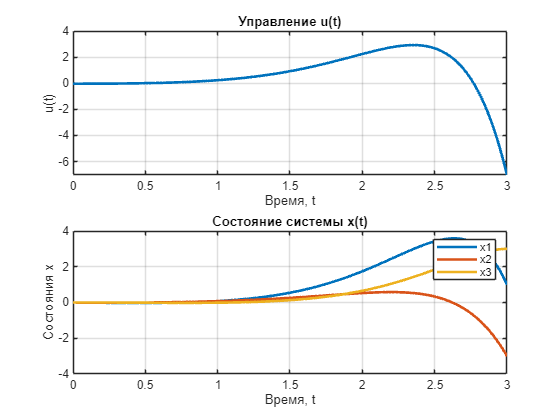

plot_control_and_state(A, B, x1, t1, gr, "figs/task_1.png");

% Transpose of A
A_T = A';

syms t

% Compute exp(A^T * (T - t))
exp_A_T = expm(A_T * (3 - t));

u = B'*exp_A_T/gr*x1

$$u = -\frac{405887719195537212572277707588776299228823552\,{\mathrm{e}}^{2\,t-6}}{19301344161402620295545842144861197749311363}+{\mathrm{e}}^{t\,\left(2-\mathrm{i}\right)-6+3\,\mathrm{i}}\,\left(\frac{66841085104317398875173118567085913155829760}{19301344161402620295545842144861197749311363}-\frac{196265090638186285960380331952845399116480512}{2757334880200374327935120306408742535615909}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(2+\mathrm{i}\right)-6-3\,\mathrm{i}}\,\left(\frac{66841085104317398875173118567085913155829760}{19301344161402620295545842144861197749311363}+\frac{196265090638186285960380331952845399116480512}{2757334880200374327935120306408742535615909}\,\mathrm{i}\right)$$

var = vpa(u)

$$var = -21.028987193917873144608747843742\,{\mathrm{e}}^{2.0\,t-6.0}+{\mathrm{e}}^{t\,\left(2.0-1.0\,\mathrm{i}\right)-6.0+3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682-71.179272437130954178071901134905\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(2.0+1.0\,\mathrm{i}\right)-6.0-3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682+71.179272437130954178071901134905\,\mathrm{i}\right)$$

var2 = real(var)

$$var2 = \mathrm{real}\left({\mathrm{e}}^{t\,\left(2.0-1.0\,\mathrm{i}\right)-6.0+3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682-71.179272437130954178071901134905\,\mathrm{i}\right)\right)+\mathrm{real}\left({\mathrm{e}}^{t\,\left(2.0+1.0\,\mathrm{i}\right)-6.0-3.0\,\mathrm{i}}\,\left(3.4630274733912669767638446526682+71.179272437130954178071901134905\,\mathrm{i}\right)\right)-21.028987193917873144608747843742\,\mathrm{real}\left({\mathrm{e}}^{2.0\,t-6.0}\right)$$

ua = vpa(u);

% Display the result
disp('Matrix exponential e^{A^T * (T - t)}:');

Matrix exponential e^{A^T * (T - t)}:


disp(exp_A_T);

$$\begin{array}{l} \left(\begin{array}{ccc} \sigma_{2}+\sigma_{3} & \sigma_{4}\,\mathrm{i}-\sigma_{5}\,\mathrm{i} & -\sigma_{4}\,\mathrm{i}+\sigma_{5}\,\mathrm{i}\\ -\sigma_{1}+\sigma_{2}+\sigma_{3} & \sigma_{1}+\sigma_{4}\,\mathrm{i}-\sigma_{5}\,\mathrm{i} & -\sigma_{4}\,\mathrm{i}+\sigma_{5}\,\mathrm{i}\\ -\sigma_{1}+\frac{\sigma_{4}}{2}+\frac{\sigma_{5}}{2} & \sigma_{1}+\sigma_{4}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)+\sigma_{5}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) & \sigma_{2}+\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,t-6}\\ \sigma_{2}=\sigma_{4}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\\ \sigma_{3}=\sigma_{5}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)\\ \sigma_{4}={\mathrm{e}}^{t\,\left(2-\mathrm{i}\right)-6+3\,\mathrm{i}}\\ \sigma_{5}={\mathrm{e}}^{t\,\left(2+\mathrm{i}\right)-6-3\,\mathrm{i}} \end{array}$$

% Данные задачи 2
A = [-1 1 0; -2 -4 -1; 2 2 -1];
B = [2; -1; 1];
x1 = [1; -3; 3];
t1 = 3;

doC(A, B);

Матрица управляемости


Co =      2    -3     2
    -1    -1     9
     1     1    -9


Ранг матрицы управляемости: 2
Система не полностью управляемая.


Собственные числа системы:
  -2.0000 + 1.0000i
  -2.0000 - 1.0000i
  -2.0000 + 0.0000i

Матрица Хаутуса для собственного числа -2.000000e+00 + 1j


Hautus =    1.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 - 1.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   2.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 - 1.0000i   1.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -2.000000e+00 + -1j


Hautus =    1.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   2.0000 + 0.0000i
  -2.0000 + 0.0000i  -2.0000 + 1.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i
   2.0000 + 0.0000i   2.0000 + 0.0000i   1.0000 + 1.0000i   1.0000 + 0.0000i


Ранг матрицы Хаутуса: 3
Собственное число управляемо.

Матрица Хаутуса для собственного числа -2 + 0j


Hautus =      1     1     0     2
    -2    -2    -1    -1
     2     2     1     1


Ранг матрицы Хаутуса: 2
Собственное число не управляемо.


Комплексная жорданова форма матрицы A:
  -2.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -2.0000 - 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.0000 + 1.0000i

Вещественная жорданова форма матрицы A:
    -2     0     0
     0    -2    -1
     0     1    -2

Вещественная P:
   -1.0000    0.7071   -0.7071
    1.0000   -1.4142         0
         0    1.4142         0

Вещественная P^{-1}:
         0    1.0000    1.0000
         0         0    0.7071
   -1.4142   -1.4142   -0.7071

Новая матрица B:
         0
    0.7071
   -2.1213



gr = gramAt(A, B, t1);

Грамиан управления в точке t = 3:
    1.1250   -0.8750    0.8750
   -0.8750    0.7500   -0.7500
    0.8750   -0.7500    0.7500

Грамиан управления в точке t = 3 всевдо-обратный:
    9.6001    5.6001   -5.6001
    5.6001    3.6000   -3.6000
   -5.6001   -3.6000    3.6000

Его собственные числа:
    2.5640
    0.0609
    0.0000



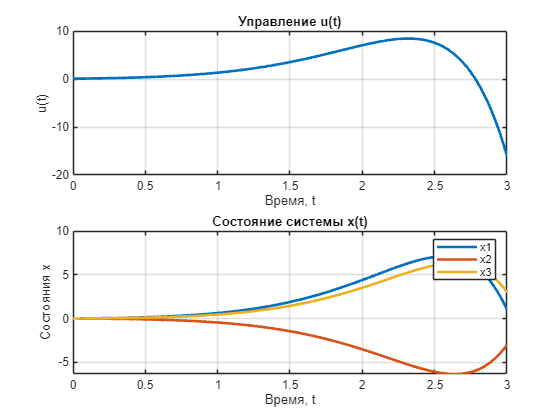

plot_control_and_state(A, B, x1, t1, gr, "figs/task_2.png");